% 增强卡尔曼滤波进行载荷识别不可行
% Reason：系统可观测性不足
clear variables

sysFull = load("Data\SimulateData\sysFull.mat");
sysReduced = load("Data\SimulateData\sysReducedChange.mat");
sysFull = sysFull.sys;
sysReduced = sysReduced.sysModal;

disTime = 0.02;
% sysFullDis = c2d(dss2ss(sysFull),disTime);
sysReducedDis = c2d(dss2ss(sysReduced),disTime);

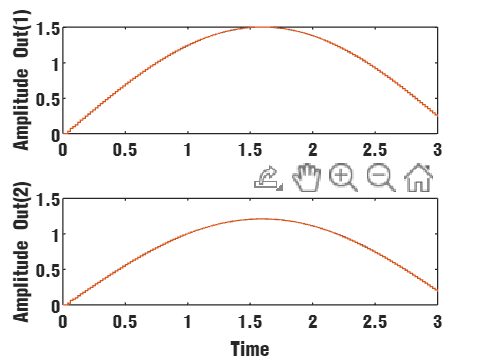

% 系统输出仿真
u = @(t) [1*sin(t) * ones(1, 1);0*sin(t) * ones(1, 1);0*sin(t) * ones(1, 1); 0*sin(t) * ones(1, 1)];
figure
opts = struct('InputFcn', u, 'TimeRange', 3);
ml_dt_dss_simulate(sysReducedDis,sysFullDis, opts);

% 构建增强状态空间方程
dimState = size(sysReducedDis.A,1);
dimInput = size(sysReducedDis.B,2);
dimOutput = size(sysReducedDis.C,1);

A_a = [sysReducedDis.A,sysReducedDis.B;zeros(dimInput,dimState),eye(dimInput)];
G_a = [sysReducedDis.C,zeros(dimOutput,dimInput)];

dimAugsystem = size(A_a,1);
sysAug = ss(A_a,eye(dimAugsystem),G_a,[],disTime);

ans =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


% 确定协方差矩阵Q and R；如何使其更准确仍有探索空间
R = 1;
% vv = [3e4 1 0.25 100 1e1 1e1]
% Q = diag(vv);
Q = 1;

% Q = [0.1*eye(4) zeros(4,2);zeros(2,4) 0.1*eye(2)];
tic
[kalmf,L,~,Mx,Z] = kalman(sysAug,Q,R);

错误使用 ss/kalman
无法计算 Kalman 滤波器的稳定 Riccati 解 P。
这可能是因为:
 * RN 是奇异矩阵，
 * [QN NN;NN' RN] 需要为正定矩阵，
 * 状态方程中的 E 矩阵是奇异矩阵。

toc

R = 1;
Q = 1;
tic
[kalmf,L,~,Mx,Z] = kalman(sysReducedDis,Q,R);
toc

历时 0.547377 秒。


% 该系统不可观，载荷识别过程中如何拓展可观测性
O = obsv(A_a,G_a);
unobsv = length(A_a) - rank(O)

unobsv = 3

sysReducedDis.B

ans = 1.0e+03 *

    1.2995    1.2995    0.8275    0.8275
   -0.0232   -0.0232   -0.0148   -0.0148
